clear; close all;
rng(100);
X1=mvnrnd([1 3],[1 0; 0 1],60);
X2=mvnrnd([4 1],[2 0; 0 2],40);
s1 = size(X1);
s2 = size(X2);
y = [ones(s1(1),1); -ones(s2(1),1)];
data = [X1;X2];

[N,l] = size(data);
c = 0.1; % c = 100;
yy = y*y';
a = data*data';
H = (yy.*a);
f = -ones(N,1);
A = [-eye(N); eye(N)];
b = [zeros(N,1); c*ones(N,1)];
Aeq = y';
beq = zeros(1);

lambda = quadprog(H,f,A,b,Aeq,beq);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


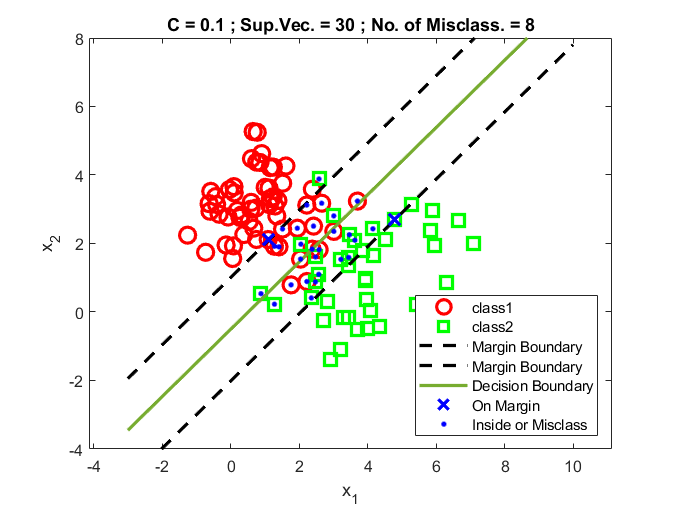


SV = find(lambda>0.001);
nSV = numel(SV);
SV_1 = find(lambda < (c*0.999) & lambda>0.001);
SV_2 = find(lambda > (c*0.999));

w = lambda'*(data.*y);
w0 = 0;
for j =1:nSV
    w0 = w0 + (y(SV(j)) - (data(SV(j),:))*w');
end
w0 = w0/nSV;
% w0 =mean(y - data*w');
W = [w w0];
y1 = X1*w' + w0;
y2 = X2*w' + w0;

misclass = 0;
for i=1 : N
    if (w*data(i,:)'+w0) * y(i) <= 0
        misclass = misclass + 1;
    end
end

range = -3:0.0001:10;
d = (w(1)*range+w0)/-w(2);
d1 = (-w(1)*range-w0+1)/w(2);
d2 = (-w(1)*range-w0-1)/w(2);
margin_width = abs(d1-d2);
figure;
plot(X1(:,1),X1(:,2), 'or',...
    X2(:,1),X2(:,2), 'sg',...
    range,d1, '--k',...
    range,d2, '--k',...
    range,d, ...
    data(SV_1,1),data(SV_1,2), 'bx',...
    data(SV_2,1),data(SV_2,2), 'b.',...
    'LineWidth',2,...
    'MarkerSize', 10);
axis equal
title(['C = ', num2str(c),' ; Sup.Vec. = ',num2str(nSV), ' ; No. of Misclass. = ', num2str(misclass)]);
legend({'class1','class2',...
    'Margin Boundary','Margin Boundary','Decision Boundary',...    
    'On Margin', 'Inside or Misclass'},'Location','southeast')
xlabel('x_{1}'); ylabel('x_{2}');

ylim([-4 8]);

% xlim([-2 8]);